# Discussão e código para resolver problema unidimensional parabólico transiente, através do Método de Elementos Finitos e Euler (implícito e explícito) e Crank-Nicolson.

#### por Raquel Mattoso 

### O problema parabólico escolhido na forma diferencial é o problema de calor

$\frac{\partial u}{\partial t} - k \frac{\partial ^2 u}{\partial x^2} = f \qquad 0<x<l, \quad t>0$,


$$u(0,t) = u(l,t) = 0 \qquad t>0,$$


$u(x,0) = u_0(x) \qquad 0<x<l$.

%%% Código desenvolvido por Raquel Mattoso para a disciplina de Método de Elementos Finitos %%%
%%% Inserindo o domínio %%%
clear; clc;
tic;
a = 0;
l = 1; % comprimento da barra 
h = 0.1; % tamanho da discretização no espaço
X = a:h:l; % conjunto de pontos de X
Xfront = h:h:(l-h); % desconsiderando pontos da fronteira
n = size(X,2);
tmax = 1.0;
t = 0;
Deltat = 0.001; % para Euler Explícito Deltat <= 1/4*h^2
cont = 1;
flag = 2; % 1 -> Implícito, 2 -> Explícito, 3-> CN, 4 -> Pós processamento
f = 0; % fonte do problema
k = 1; % capacidade térmica
u0t = 0; ult = 0; % condição de contorno dirichlet homogêneo
ux0 = 1/(pi*pi)*sin(pi*Xfront); ux0 = ux0'; % condição inicial

Para usar o método de elementos finitos é preciso colocar o problema direto na forma variacional, como segue abaixo

           
$$\int_a^l \frac{\partial u}{\partial t} + k \int_a^l\frac{\partial u}{\partial x} \frac{\partial \eta}{\partial x} dx = \int_a^l f \eta dx, \qquad \forall \eta \in \mathcal{V}

$$


            $\mathcal{V} = \{\eta \in H; \eta(a) = \eta(b) =0\}$.

A partir disso, podemos construir as funções base lineares em um determinado elemento como

            
$$\phi(x) =  \frac{x-x_{i-1}}{d}, \qquad x_{i-1} \leq x \leq x_i \\ \phi(x) = \frac{x_{i+1}-x}{d}, \qquad x_{i} \leq x \leq x_{i+1} \\ \phi(x) = 0, \qquad cc $$


Então, podemos computar as funções lineares base e suas respectivas derivadas como segue 

syms x % tratado como símbolo
phi1(x) = x/h; 
phi2(x) = (h-x)/h;
dphi1(x) = diff(phi1(x));
dphi2(x) = diff(phi2(x));

Após aplicar diferenças finitas para substituir a derivada em relação ao tempo é possível escrever o problema variacional na forma discreta genérica abaixo.


$$\int_0^l \phi_i^t \phi_j+ k \Delta t \int_0^l \frac{\partial \phi^t_i}{\partial x} \frac{\partial \phi_j}{\partial x} dx = \Delta t\int_0^l f\phi_j dx + \int^l_0 \phi_i^{t-1}\phi_j dx, \qquad \forall \phi_j \in \mathcal{V_h}

$$


Note que $f$ não depente do tempo. Isto é devido a construção do problema, mantemos a fonte fixa para todo t. $V_h$ é um subconjunto finito do espaço $V
$. Como de costume, o problema pode ser escrito como um sistema linear do tipo: 

$\sum_j A_{i,j} u_j = b_i $, em que 


$$A_{i,j} = \sum_{j=0}^N (\phi_i,\phi_j) +  \Delta t \times k\sum_{j=0}^N (\frac{\partial \phi_j^t}{\partial x},\frac{\partial \phi_j}{\partial x}) u_{j} \\ b_i = \sum_{j=0}^N (\phi_i^{t-1},\phi_j)+ \Delta t (f,\phi_i) $$


Para facilitar a implementação, vamos definir as matrizes Massa e Rigidez como 


$$ M = \sum_{j=0}^N (\phi_i^t,\phi_j), \quad K = k \sum_{j=0}^N (\frac{\partial \phi_j^t}{\partial x},\frac{\partial \phi_j}{\partial x}) $$
 

Com as informações acima é possível fazer as implementações dos três métodos pedidos no problema. 

### Problema Evolutivo

Quando trabalhamos um problema com solução numérica no transiente, temos duas partes: a parte iterativa que é relacionada a encontrar a solução numérica no espaço e a evolutiva que faz o processo de evolução do fenômeno físico no tempo. A solução iterativa é considerada a mesma para todos os cenários, pois usa elementos finitos, as mudanças serão relativas justamente aos métodos numéricos para transiente. Então, podemos contruir de imediato as matrizes Massa (M) e Rigidez (K), como segue

M = zeros(n-2,n-2); K = zeros(n-2,n-2);
for j=1:(n-2)
    for i=1:(n-2)
        if i==j
            M(i,j) = int(phi1*phi1,0,h) + int(phi2*phi2,0,h);
            K(i,j) = k*(int(dphi1*dphi1,0,h) + int(dphi2*dphi2,0,h));
        end
        if i==j+1 || i==j-1
            M(i,j) = int(phi1*phi2,0,h);
            K(i,j) = k*int(dphi1*dphi2,0,h);
        end
    end
end

### EULER IMPLÍCITO

Para o caso do Euler implícito, o problema pode ser rescrito como:


$$Mu_h^t + \Delta t Ku_h^t= Mu_{h}^{t-1} + \Delta t f$$


if flag == 1
    aux = Deltat*(int(phi1*f,0,h)+ int(phi2*f,0,h));
    while t <= tmax
        B = M*ux0 + aux;
        B(1,1) = B(1,1) - u0t; B(n-2,1) = B(n-2,1) - ult;
        ux = (Deltat*K+M)\B;
        ux0 = eval(ux);
        uh = [0,ux0',0];
        EI(cont,:) = uh(1,:);
        cont = cont + 1;
        t = t+Deltat;
    end
    save 'EI.mat' EI;
    toc;
    time = toc;
    save timeEI.mat time;    
end

### Euler Explícito 

Para o caso do Euler implícito, o problema pode ser rescrito como:


$$Mu_h^t = - \Delta t Ku_h^{t-1} + Mu_{h}^{t-1} + \Delta t f$$


Cabe aqui o comentário de que o método do Euler Explícito não é incondicionalmente convergente, como o Implícito, por isto, demanda que o tamanho da discretização no tempo tenha relação com o tamanho da discretização no espaço como

$\Delta t \leq \frac{1}{4}h^2$, 

Com o objetivo de conseguir gráficos consistentes entre os três métodos, será usado o $\Delta t$ exigido para convergência do método Euler Explícito para todos. 

if flag == 2
    aux = Deltat*(int(phi1*f,0,h)+int(phi2*f,0,h));
    while t <= tmax
        B = (M - Deltat*K)*ux0 + aux;
        B(1,1) = B(1,1) - u0t; B(n-2,1) = B(n-2,1) - ult;
        ux = M\B; 
        ux0 = (ux);
        uh = [0,ux0',0];
        EE(cont,:) = uh(1,:);
        cont = cont +1;
        t = t+Deltat;
    end
    save EE.mat EE;
    toc;
    time = toc;
    save timeEE.mat time; 
end

### Crank - Nicolson

No caso de usar o método ponderado de Crank - Nicolson, o problema pode ser rescrito como:


$$Mu_h^t + \frac{1}{2}\Delta t Ku_h^t = Mu_h^{t-1} -  \frac{1}{2}\Delta t Ku_{h}^{t-1}  + \Delta t f$$


if flag == 3
    aux = Deltat*(int(phi1*f,0,h)+int(phi2*f,0,h));
    while t <= tmax
        B = (M - 1/2*Deltat*K)*ux0 + aux;
        B(1,1) = B(1,1) - u0t; B(n-2,1) = B(n-2,1) - ult;
        ux = (M+(Deltat/2)*K)\B;
        ux0 = eval(ux);
        uh = [0,ux0',0];
        CN(cont,:) = uh(1,:);
        cont = cont + 1;
        t = t+Deltat;
    end
    save CN.mat CN;
    toc;
    time = toc;
    save timeCN.mat time; 
end

Pós processamento

if flag == 4
     %EI = importdata('EI.mat');
     EE = importdata('EE.mat');
     CN = importdata('CN.mat');
     aux = tmax/Deltat;
    for i=1:aux
        Exata(i,:) = (1.0/(pi*pi))*sin(pi*X)*exp(-(k*pi*pi)*i*Deltat);
    end 
    
%     figure(1);
%     plot(X,Exata(1,:),'k'); hold on;
%     plot(X,EI(1,:),'b'); hold on;
%     plot(X,EE(1,:),'r'); hold on;
%     plot(X,CN(1,:),'g'); legend('Exata','Euler Implícito','Euler Explícito','Crank-Nicolson'); 
%     title('Comparação entre as soluções para t=0.0');ylabel('$u_h$','interpreter','latex'); 
%     xlabel('$x$(u.m.)','interpreter','latex');
%     
%     figure(2);
%     plot(X,Exata(aux,:),'k'); hold on;
%     plot(X,EI(aux,:),'b'); hold on;
%     plot(X,EE(aux,:),'r'); hold on;
%     plot(X,CN(aux,:),'g'); legend('Exata','Euler Implícito','Euler Explícito','Crank-Nicolson'); 
%     title('Comparação entre as soluções para t=1.0'); ylabel('$u_h$','interpreter','latex'); 
%     xlabel('$x$(u.m.)','interpreter','latex');
%         
    for i=1:(tmax/Deltat)
        %ErroEI(i) = norm(Exata(i,:)-EI(i,:));
        ErroEE(i) = norm(Exata(i,:)-EE(i,:));
        %ErroCN(i) = norm(Exata(i,:)-CN(i,:));
    end
    figure(3);
    tempo = 0:Deltat:tmax;
    %plot(tempo,ErroEI,'b'); hold on;
    ErroEE = [0,ErroEE];
    plot(tempo,ErroEE,'r'); hold on;
    %plot(tempo,ErroCN,'g'); legend('Euler Explícito','Clark-Nicolson');
    title('Erro para k=-1'); 
    xlabel('$t$(u.t.)','interpreter','latex'); ylabel('$\|Exata - Numerica\|$','interpreter','latex');
end

### Análises requeridas

***Item 1***

Para mostrar que os métodos e o código estão corretos, foi plotado o resultado da solução analítica e das soluções numéricas encontradas para t=0.0s e t = 1.0s, respectivamente as Figuras 1 e 2, abaixo. 

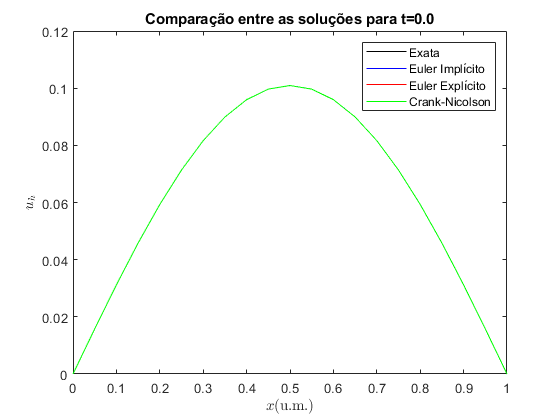

Figura 1: Resultado para a comparação entre as soluções analítica(exata) e as númericas para t = 0.0 u.t.

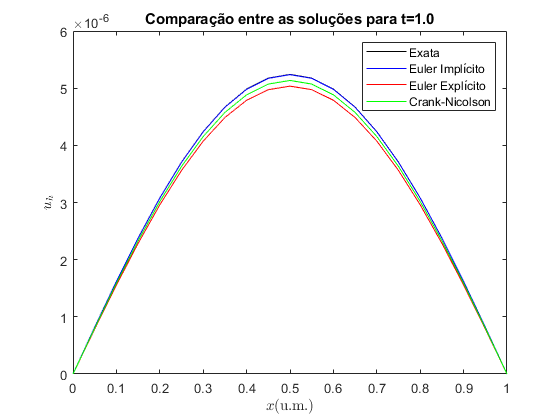

Figura 2: Resultado para a comparação entre as soluções analítica(exata) e as númericas para t = 1.0 u.t

Note que para t=0 as solução são idênticas o que já era esperado pois partem do mesmo valor inicial. Ao longo do tempo a solução muda, pois há erros numéricos dos métodos Euler Implícito e Explícito e Crank-Nicolson atrelados. Com o objetivo de analisar estes erros, foi plotada a Figura 3 que mostra os erros na norma eucliadiana a cada passa no processo evolutivo. 

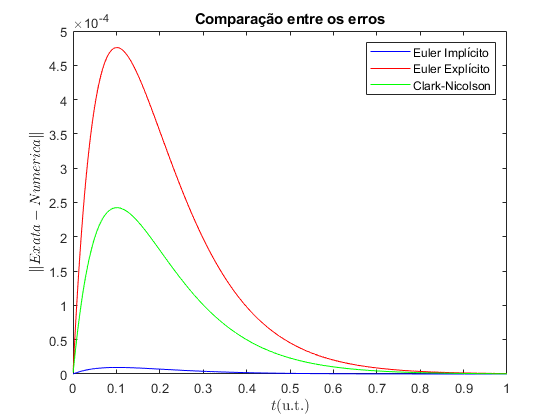

Figura 3: Comparação entre os erros obtidos em relação a solução exata.

***Item 2***

Se invertermos o sinal de $\frac{\partial u}{\partial t}$, o problema de calor passa a ser reescrito como 

$\frac{\partial u}{\partial t} = - k \frac{\partial ^2 u}{\partial x^2} + f \qquad 0<x<l, \quad t>0$.

Em termos de implementação basta apenas trocar o sinal de k, o resultado obtido para o erro foi o mostrado na Figura 4.

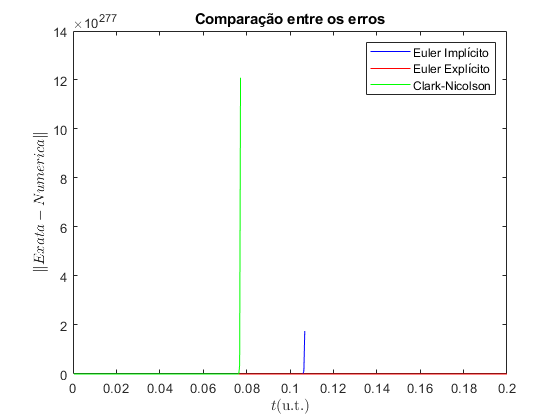

Figura 4: Comparação entre os erros obtidos em relação a solução exata, para k=-1.

Na Figura 4 podemos observar que o erro explode, mesmo com um tempo de evolução bastante pequeno. Perceba que os resultados obtidos se tornam não numéricos e por isso não aparecem mais no gráfico. Conforme a solução exata e numérica crescem exponencialmente, visto que com k=-1 a exponencial, que é solução exata para o problema parabólico analisado, passa a ter expoente positivo, o erro cresce absurdamente.  

***Item 3 - ***Escolheu-se para violar a condição de estabilidade do método Euler Explícito o $\Delta t = 0.01$. A Figura 5 abaixo, mostra o resultado. Como era esperado o erro em relação a solução exata explode. 

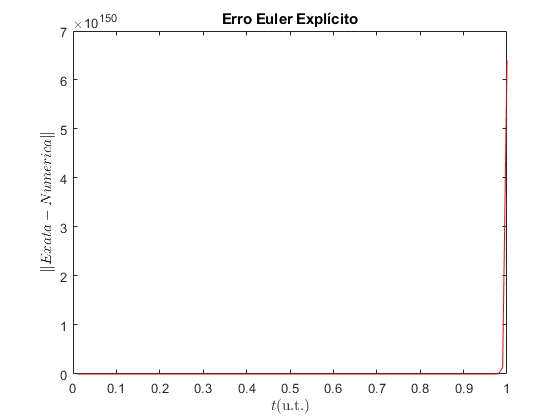

Figura 5: Resultado para o erro do método de Euler Explícito utilizando discretização no tempo maior do que o imposto pela condição de estabilidade. 

***Item 4 - Tempos de execução***

Os tempos abaixo são referentes a $h=0.05 \text{ e } \Delta t=0.0004 $.

- Euler Implícito - t = 146.42 segundos de execução

- Euler Explícito - t = 14.01 segundos de execução

- Crank-Nicolson - t = 134.51 segundos de execução

Os tempos são relativamente altos quando comparado com códigos rodados em C, por exemplo. Este ambiente do matlab é mais pesado e acaba influenciando no desempenho do código. Entretanto, como o objetivo aqui era a implementação e não necessariamente um código de alto desempenho, não há grandes preocupações. Os tempos de forma relativa estão dentro do esperado, sendo sempre o Euler Explícito muito mais rápido do que os outros dois. 

No caso do Matlab a maneira de resolver um sistema linear já é feita de forma otimizada através do comando A\B. Então, calcular a inversa por fora e multiplicar a cada iteração já resulta em um tempo de execução maior do que o encontrado acima para o Euler Implícito por exemplo, que seria t=242.94s, quando fazemos a inversa a cada iteração o tempo de execução é ainda superior sendo t=268.69s. Não fosse uma otimização da linguagem, certamente seria mais eficiente multiplicar a inversa da matriz pela vetor B do que calcular a inversa a cada iteração. 